# Tracking control with state-space methods 

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours and analysis. A common linear model type is the state-space model. 

When a system is expressed as a state-space model tracking is not as straightforward as in the transfer function case. Using conventional block diagram approaches we know that integral control is normally adequate to ensure offset free tracking in the steady-state, and moreover will do so in the presence of some uncertainty. However, typical PID designs and block diagrams have control laws that are based solely on output measurements, whereas with state-space models it is more normal to deploy state feedback.  Consequently we need to rethink how tracking is introduced into the feedback design.

This resource introduces simple methods for dealing with non-zero constant targets and then looks more systematically at how integral action can be incorporated into a state-space framework, with an observer and model uncertainty. 

Lots of code snippets are provided as examples of how MATLAB can be used and the intention is that readers can use these as exemplars and/or templates and change the models and scenarios for their own need. 

It makes more sense to use simulink to both code and investigate these issues so later files will refer to the associated simulink files as required (e.g. ***state_space_and_simulinkfile1_control101, state_space_and_simulinkfile2_control101, state_space_and_simulinkfile3_control101***).

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% There is a bug in 2024a: Try doc ("Control101 Toolbox")  or doc control101_toolbox. 
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, Ross Drummond, Lanlan Su (University of Sheffield) and Ruth Bars (Budapest University of Technology and Economics)                       

    

## Table of Contents

- Background on simplistic feedforward design

- Examples of feedforward design with MATLAB

- Including integral action into a state-space feedback design

- MATLAB code demonstrating the inclusion of integral action

## 1. Background on simplistic feedforward design

A typical state-space system with simple state feedback is given here:

$\dot{X} =A\;X+B\;U;\;Y=C\;X+d,\;$  $U=-K\;X$   (1.1)

with state *X*, input *U* and output *Y *and* d *an output disturbance*. *This system will regulate the state to zero, assuming no disturbances. 

### 1.1 The nominal case

In practice it is common to have non-zero targets and thus we need to modify the state feedback accordingly to have some dependence on the target value. For example, a simplistic approach would use:

$U=-K\;X+P\;r$     (1.2)

where *P* is the feedforward (FF) gain and* r* is the target. 

One can easily speculate on what would be a suitable value for *P* to ensure steady-state offset free tracking in the nominal case (use the subscript 'ss' to denote a steady-state).


$$\left\lbrace Y_{\textrm{ss}} =CX_{\textrm{ss}} =r;\;AX_{\textrm{ss}} -B\;KX_{\textrm{ss}} +B\;P\;r=0\right\rbrace \;\;\Rightarrow -C{\left\lbrack A-B\;K\right\rbrack }^{-1} B\;P\;r=r$$


So: 

$P=-\;{\left(C{\left\lbrack A-B\;K\right\rbrack }^{-1} B\right)}^{-1}$  (1.3)

**Remark**: One can show that such a *P* is analogous to another popular format based on deviation variables relative to a steady-state. This is the following state feedback law:


$$\left(U-U_{\textrm{ss}} \right)=-K\left(X-X_{\textrm{ss}} \right);\;\;\;\;U_{\textrm{ss}} =k_u r,\;\;X_{\textrm{ss}} =k_x r;\;\;\;\;\;U_{\textrm{ss}} +KX_{\textrm{ss}} =P\;r$$


In this case consistent steady-state inputs and states need to be estimated.

### 1.2 Selected uncertain cases

Of course, in practice there will be parameter errors and also input/output disturbances. Hence use of the value given in equation (1.2) will lead to offset, as demonstrated here.

Take the case of a simple output disturbance so that: $Y=C\;X+d,$ with *d* unknown. Then, as we have state feedback (the outputs do not impact on the feedback term and the states are not affected by this disturbance) there will clearly be an offset of *d* in the steady-state.


$$\left\lbrace Y_{\textrm{ss}} =CX_{\textrm{ss}} +d;\;AX_{\textrm{ss}} -B\;KX_{\textrm{ss}} +B\;P\;r=0,P=-\;{\left(C{\left\lbrack A-B\;K\right\rbrack }^{-1} B\right)}^{-1} \right\rbrace \;\;\Rightarrow \;\;\;\;Y_{\textrm{ss}} =r+d$$


In the case of parameter uncertainty (use subscript 'm' for the model used in the control design steps), even with no disturbances, the following equations show that there will also be an offset as the two terms in the steady-state expression are no longer inverses one of another.


$$\left\lbrack \begin{array}{c}
Y_{\textrm{ss}} =CX_{\textrm{ss}} =r;\;AX_{\textrm{ss}} -B\;KX_{\textrm{ss}} +B\;P\;r=0,\;\\
U=-K\;X+P\;r,\;\;P=-\;{\left(C_m {\left\lbrack A_m -B_m \;K\right\rbrack }^{-1} B_m \right)}^{-1} 
\end{array}\right\rbrack \;\;\Rightarrow \;\;\;\;Y_{\textrm{ss}} =\underbrace{C{\left\lbrack A-B\;K\right\rbrack }^{-1} B} {\;\;\;\;\;\underbrace{\left(C_m {\left\lbrack A_m -B_m \;K\right\rbrack }^{-1} B_m \right)} }^{-1} r\not= I\;r$$


## 2. Examples of Feedforward design with MATLAB

This section will demonstrate how the simplistic design of Section 1 will give no offset in the nominal case, but an offset in the uncertain cases. The control designs for the state feedback are notional and not important.

For simplicity of illustration the code develops a state-space model to represent the closed-loop, that is:


$$\dot{X} =\left(A-B\;K\right)\;X+B\;P\;r\;;\;Y=C\;X+d$$


In the case of parameter uncertainty the compensators *K, P* are based on the model information, not the actual system parameters.

### 2.1 Nominal case - closed-loop gain is unity

In this case there is no model uncertainty and no disturbances. The FF delivers the desired target; here we use unity for convenience.

disp('Section 2.1 - example 1: SISO case')

Section 2.1 - example 1: SISO case


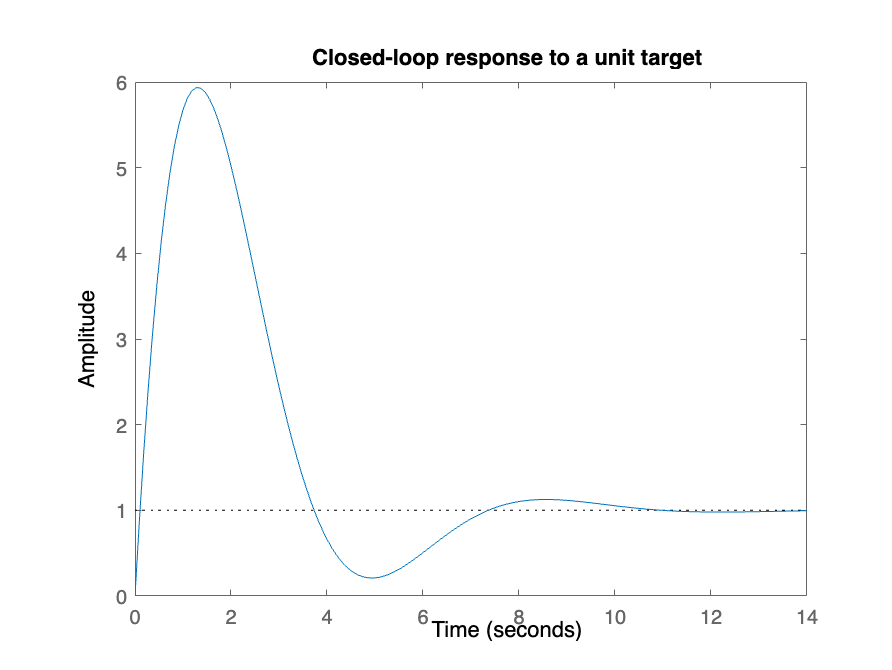

A = [0 1; -1 -0.1]; 
B = [1; 0]; 
C = [1 0]; D = 0;
% Control design
Q = C'*C; R=1;
Km=lqr(A,B,Q,R);
% Feedforward design
P = -inv(C*inv(A-B*Km)*B);
% Closed-loop model
Gclosed = ss(A-B*Km,B*P,C,0);
step(Gclosed)
title('Closed-loop response to a unit target')


disp('Section 2.1 - example 2: MIMO case')

Section 2.1 - example 2: MIMO case


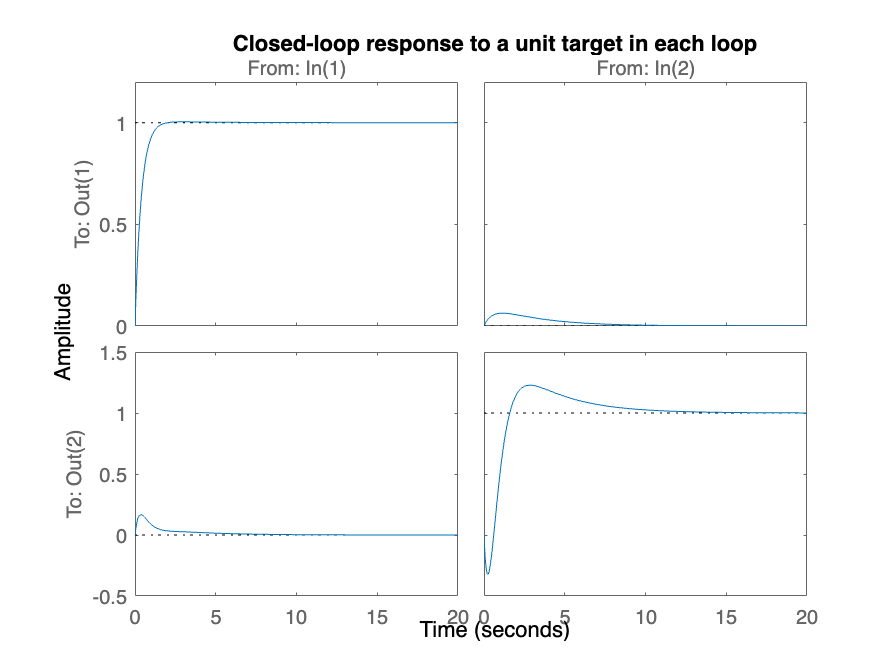

A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
C=[3 2 1 0;0 0 0 1];
D = zeros(2,2);
% Control design
Q = C'*C; R=1;
Km=lqr(A,B,Q,R);
P = -inv(C*inv(A-B*Km)*B);
% Closed-loop model
Gclosed = ss(A-B*Km,B*P,C,D);
step(Gclosed)
title('Closed-loop response to a unit target in each loop')

### 2.2 Uncertain case disturbances

Treat the disturbance as an additional input, so augment the *B* and *D* matrices as required (after the design of *K* and *P*)  to make MATLAB produce the desired plots. Hence the closed-loop model is:


$$\dot{X} =\left(A-B\;K\right)\;X+\left\lbrack \begin{array}{cc}
B\;P & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
d
\end{array}\right\rbrack \;;\;Y=C\;X+\left\lbrack \begin{array}{cc}
0 & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
d
\end{array}\right\rbrack$$


disp('Section 2.2 - example 1: SISO case with a disturbance')

Section 2.2 - example 1: SISO case with a disturbance


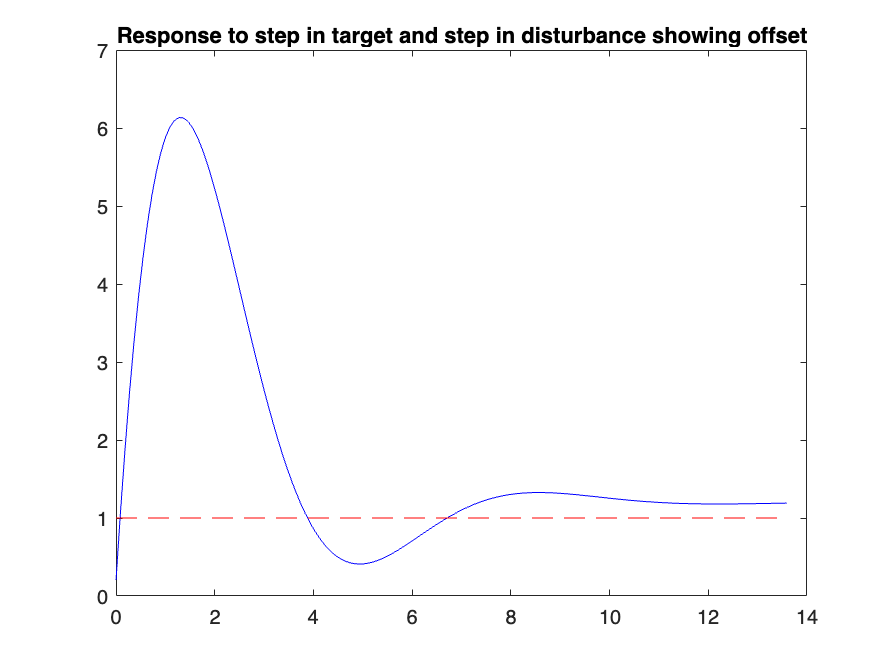

A = [0 1; -1 -0.1]; 
B = [1 0;0 0];   % output disturbance so add a column of zeros to B
C = [1 0]; 
D = [0 0.2];     % add small extra column as disturbance impact normally small
% Control design
Q = C'*C; R=1;
Km=lqr(A,B(:,1),Q,R);
% Feedforward design
P = -inv(C*inv(A-B(:,1)*Km)*B(:,1));  % Only include 1st column of B in FF design
P = [[P;0],[0;0]];                    % Add row/col for extra input
Km = [Km;0 0];
% Closed-loop model
Gclosed = ss(A-B*Km,B*P,C,D);
[y,t] = step(Gclosed);
plot(t,y(:,:,1)+y(:,:,2),'b',[t(1),t(end)],[1 1],'r--')
title('Response to step in target and step in disturbance showing offset')

For the MIMO case, the plot focuses on just on the responses to a single disturbance/target but it will be obvious from the code how to add more disturbances if desired. 


disp('Section 2.2 - example 2: MIMO case')

Section 2.2 - example 2: MIMO case


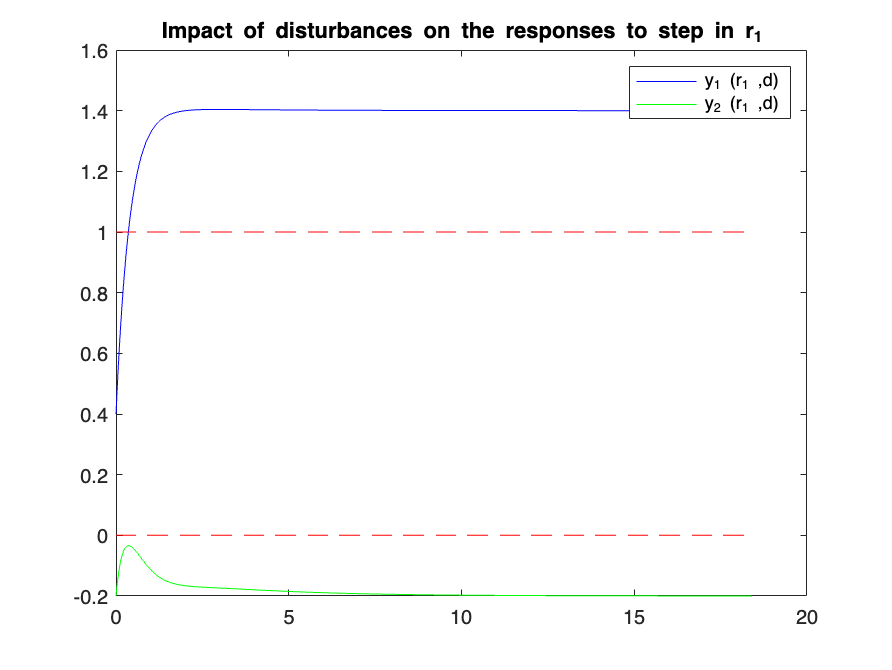

A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[[1 0;-1 1;0 0.3;-1 2],[0;0;0;0]]; % output disturbance so add a column of zeros to B
C=[3 2 1 0;0 0 0 1];
D = [zeros(2,2),[0.4;-0.2]];  % add small extra column as disturbance impact normally small
% Control design
Q = C'*C; R=1;
Km=lqr(A,B(:,1:2),Q,R);
P =-inv(C*inv(A-B(:,1:2)*Km)*B(:,1:2));
% Add row/col for extra input
P = [[P; 0 0 ],[0; 0; 0]]; 
Km = [Km;0 0 0 0];
% Closed-loop model
Gclosed = ss(A-B*Km,B*P,C,D);
[y,t] = step(Gclosed);
plot(t,y(:,1,1)+y(:,1,3),'b',t,y(:,2,1)+y(:,2,3),'g',[t(1),t(end)],[1 1],'r--',[t(1),t(end)],[0 0],'r--')
title('Impact of disturbances on the responses to step in r_1')
legend('y_1 (r_1 ,d)','y_2 (r_1 ,d)')

### 2.3 Uncertain case - closed-loop gain is no longer unity

This section shows that when parameter uncertainty is included, then the FF no longer delivers offset free tracking because: $\underbrace{C{\left\lbrack A-B\;K\right\rbrack }^{-1} B} {\;\;\;\;\;\underbrace{\left(C_m {\left\lbrack A_m -B_m \;K\right\rbrack }^{-1} B_m \right)} }^{-1} \not= I$

disp('Section 2.3 - example 1: SISO case with parameter uncertainty')

Section 2.3 - example 1: SISO case with parameter uncertainty


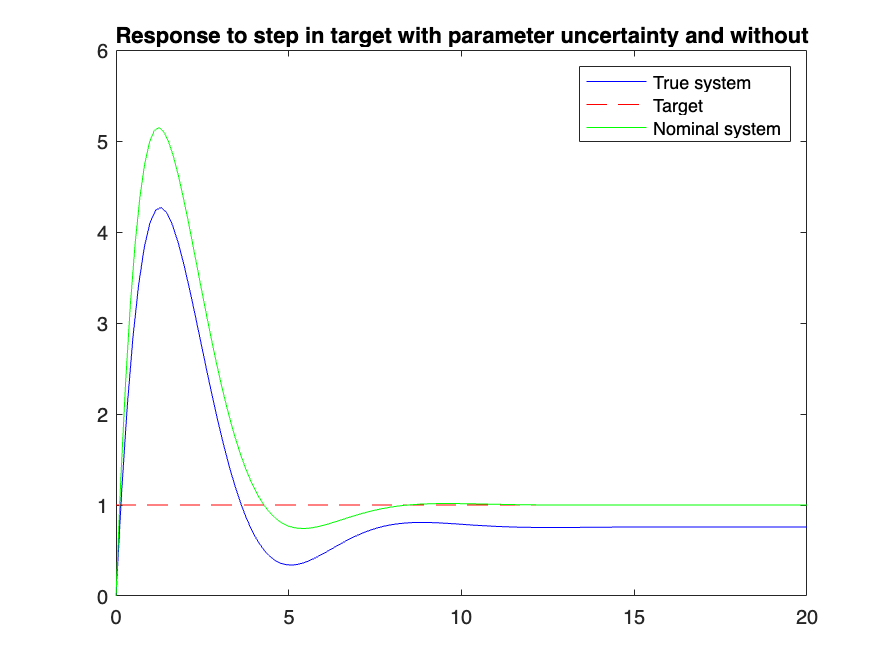

A = [0 1; -1 -0.1]; 
B = [1 ;0];  
C = [1 0]; 
D=0;
Am=A; 
Bm = [1.2;0];  
Cm = [1.1 0];

% Control design
Q = Cm'*Cm; R=1;
Km=lqr(Am,Bm,Q,R);
% Feedforward design
P = -inv(Cm*inv(Am-Bm*Km)*Bm);  

Gclosed = ss(A-B*Km,B*P,C,D);
Gclosed0 = ss(Am-Bm*Km,Bm*P,Cm,D);
[y,t] = step(Gclosed,20);
[y0,t0] = step(Gclosed0,20);
plot(t,y(:,:,1),'b',[t(1),t(end)],[1 1],'r--', ...
    t0,y0(:,:,1),'g')
title('Response to step in target with parameter uncertainty and without')
legend('True system', 'Target','Nominal system')




disp('Section 2.3 - example 2: MIMO case with parameter uncertainty')

Section 2.3 - example 2: MIMO case with parameter uncertainty


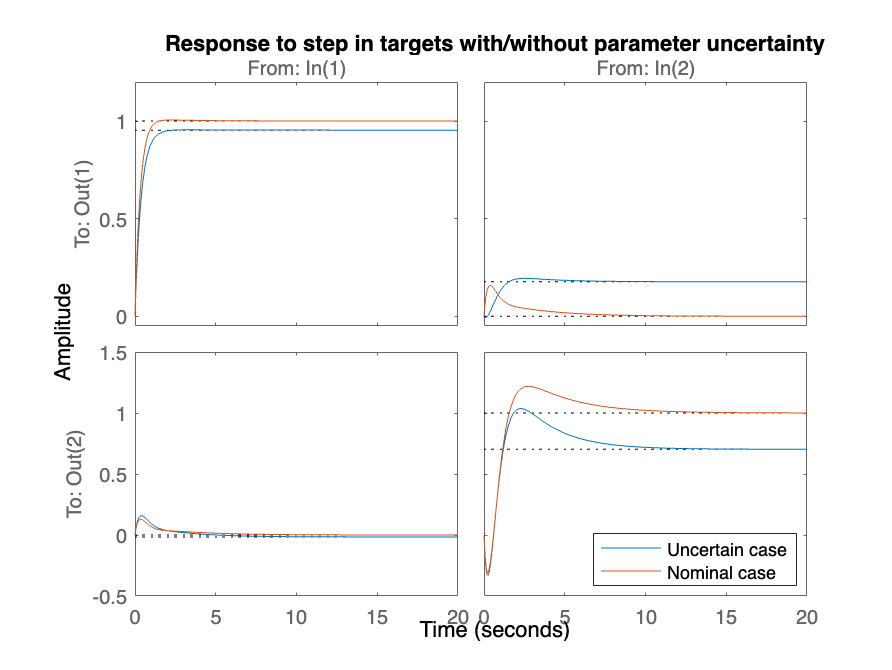

A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
C=[3 2 1 0;0 0 0 1];
D = zeros(2,2);
%    Model parameters differ from true system
Am=[-0. -0.4 -0.65 0.2;0.4 1 .72 .5;-0.3 1 1 0;0.8 1.1 -0.4 0]; 
Bm=[1.2 0;-1 1;0 0.35;-1.1 2];
Cm=[3.2 2 1 0;0 0 0 1];

% Control design
Q = Cm'*Cm; R=1;
Km=lqr(Am,Bm,Q,R);
% Feedforward design
P = -inv(Cm*inv(Am-Bm*Km)*Bm);  
Gclosed = ss(A-B*Km,B*P,C,D);
Gclosed0 = ss(Am-Bm*Km,Bm*P,Cm,D);
step(Gclosed,Gclosed0,20);
title('Response to step in targets with/without parameter uncertainty')
legend('Uncertain case','Nominal case','Location','southeast')

## 3. Including integral action into a state-space feedback design

A simple method used in traditional control to remove steady-state offset is to include the integral of the error within the feedback law.


$$z=\int_0^t \left(r-Y\left(t\right)\right)\textrm{dt};\;\;\;U\left(t\right)=f\left(z,\cdots \right)$$


The reason this works is because *z* will keep changing if the error is not zero, and thus the control signal *U(t)* will also keep changing. It is only possible to have an asympotic steady-state if *z* is constant which means the tracking error must be zero. Implicitly z has the same dimension as the number of outputs. Hence, the proposal here is to create a new state/s in the state-space model to capture this term, that is:


$$\frac{d\;Z}{d\;t}=r-C\;X$$


Next ensure that the state feedback depends upon this new state *Z*, and indeed ensure that the state feedback is driving *Z* to a constant, which implies the offset must be zero. Hence, the augmented system model becomes:


$$\left\lbrace \left\lbrack \begin{array}{c}
\dot{X} \\
\dot{Z} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & 0\\
-C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\\
0
\end{array}\right\rbrack U+\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r\right\rbrace \;\;\;\Rightarrow \;\left\lbrace \dot{W} =A_{\textrm{aug}} W+B_{\textrm{aug}} U+\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r;\;W=\left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack \right\rbrace$$


In the first instance, find a stabilising state feedback of the form:  $U=-K\;W$ for the augmented system;  we can worry about how to integrate the target in a second step as this is not an input that can be modified, so should not be part of the feedback loop.


$$\left\lbrack \begin{array}{c}
\dot{X} \\
\dot{Z} 
\end{array}\right\rbrack =\left(\left\lbrack \begin{array}{cc}
A & 0\\
-C & 0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
B\\
0
\end{array}\right\rbrack K\right)\left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r;\;\;\;\;\;\;Y=\left\lbrack \begin{array}{cc}
C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack$$


**Remark**: The inclusion or not of an explicit feedforward term of the type: $U=-K\;W+P\;r$ effects the transient behaviour of the overall control design and the steady-state value of Z. However, it does not impact on the steady-state or closed-loop poles or indeed the choice of *K*. One can see that including this gives an immediate heads up of the desired steady-state (much like the proportional component of a PI) so the input will change more quickly during transients. A logical choice for* P* would the one from section 1 above and the simulations below will demonstrate the difference between including or excluding this term. See section 5 for a longer discussion on this.


$$\left\lbrack \begin{array}{c}
\dot{X} \\
\dot{Z} 
\end{array}\right\rbrack =\left(\left\lbrack \begin{array}{cc}
A & 0\\
-C & 0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
B\\
0
\end{array}\right\rbrack K\right)\left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\;P\\
0
\end{array}\right\rbrack r+\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r;\;\;\;\;\;\;Y=\left\lbrack \begin{array}{cc}
C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack r$$


**Remark**: With disturbances the model has a small augmentation. First note that in effect: $\frac{d\;Z}{d\;t}=r-C\;X-d$ (in reality you use the actual output measurement). Hence the model is:


$$\left\lbrack \begin{array}{c}
\dot{X} \\
\dot{Z} 
\end{array}\right\rbrack =\left(\left\lbrack \begin{array}{cc}
A & 0\\
-C & 0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
B\\
0
\end{array}\right\rbrack K\right)\left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
B\;P & 0\\
I & -I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
d
\end{array}\right\rbrack ;\;\;\;\;\;\;Y=\left\lbrack \begin{array}{cc}
C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r\\
d
\end{array}\right\rbrack$$


## 4. MATLAB code demonstrating the inclusion of integral action

The code here shows how one can easily construct the augmented models and state feedback terms and closed-loop systems to demonstrate the impact of integral action in a state-space system. The code replicates the closed-loop models given in Section 3 above and demonstrates clearly that the integral action rejects both parameter uncertainty and output disturbances, whereas the methods in Sections 1-2 failed to do this.

**Remarks**: 

- For brevity the input signals are not computed using the code below, again because this is fiddly but in truth a complete analysis should also evaluate these.

- Readers will note that the coding is somewhat fiddly to create representative models for each scenario although this means it is quick and easy to change numbers and investigate concepts. In general it is probably better to use simulink models to investigate these issues as summarised in the files: ***state_space_and_simulinkfile1_control101, state_space_and_simulinkfile2_control101, state_space_and_simulinkfile3_control101***.

### 4.1 Integral action and no uncertainty

disp('Section 4.1 - example 1: SISO case with and without uncertainty')

Section 4.1 - example 1: SISO case with and without uncertainty


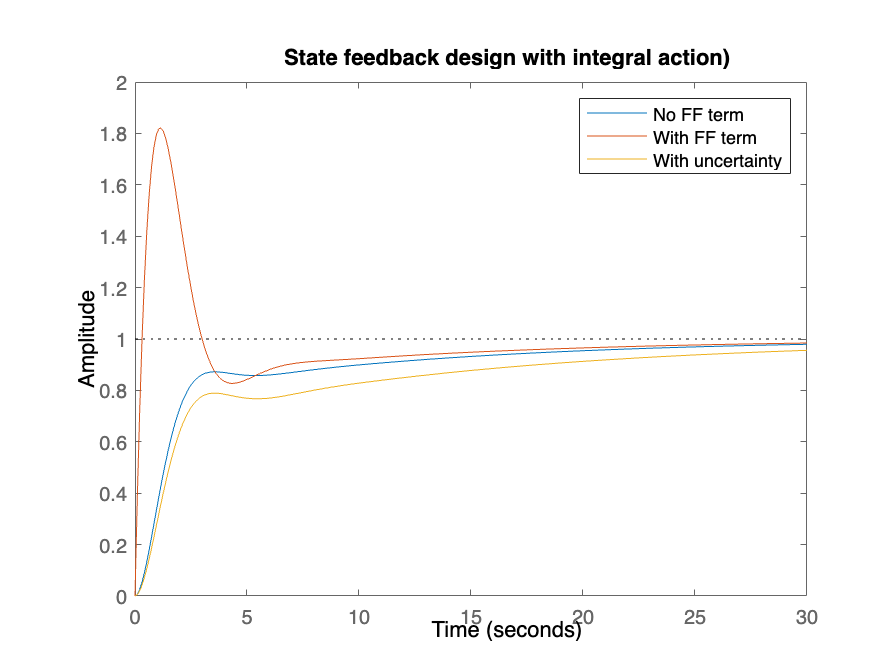

% True system
A = [0 1; -1 -0.1]; 
B = [1; 0]; 
C = [1 0]; D = 0;
%    Model parameters differ from true system
Am=A; 
Bm = [1.2;0];  
Cm = [1.1 0];
% Augmented model and  augmented process
Aaugm = [Am,[0 ;0];-Cm,0];
Baugm = [Bm;0];
Caugm = [Cm,0];
Aaugp = [A,[0 ;0];-C,0];
Baugp = [B;0];
Caugp = [C,0];

% Control design
Qaug = [Cm'*Cm,[0 ;0];0,0,1]; 
Raug=1;
Km=lqr(Aaugm,Baugm,Qaug,Raug);
% Feedforward design
P = -inv(Cm*inv(Am-Bm*Km(:,1:2))*Bm);  % use the part of K not depending on the error state
Br = [0;0;1];
BrP = [B*P;1];

% Closed-loop model nominal case
Gclosed = ss(Aaugm-Baugm*Km,Br,Caugm,0);  % with no FF
GclosedP = ss(Aaugm-Baugm*Km,BrP,Caugm,0);  % with  FF

% Closed-loop model with parameter uncertainty
Gclosed_p = ss(Aaugp-Baugp*Km,Br,Caugp,0);  % with no FF
%Gclosed_pP = ss(Aaugp-Baugp*K,BrP,Caugp,0);  % with  FF




step(Gclosed,GclosedP,Gclosed_p,30)
title('State feedback design with integral action)')
legend('No FF term','With FF term','With uncertainty')

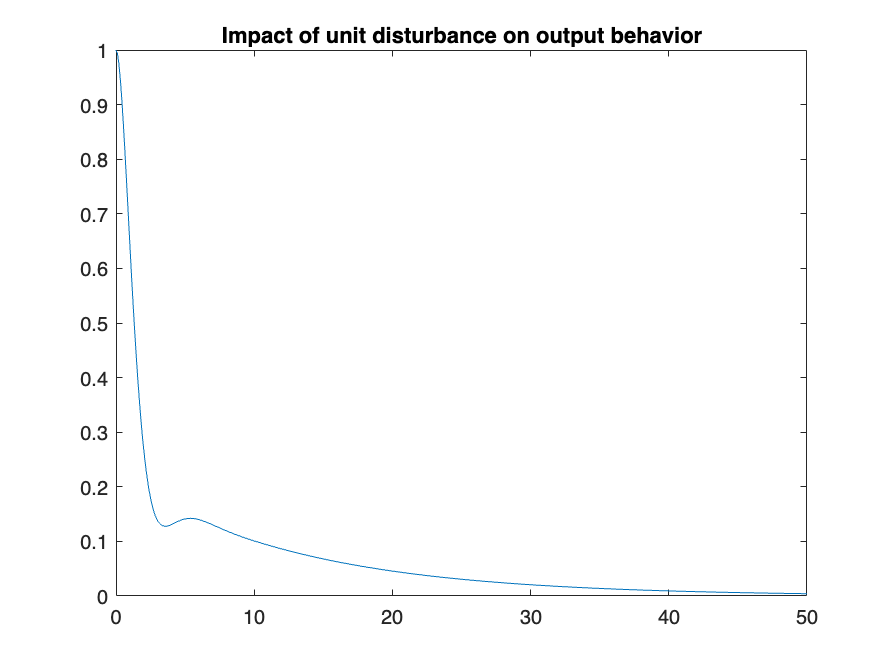


% Augmentation for disturbance case
Bd = [Br,[0;0;-1]];   % output disturbance so add a column of zeros to B
Cd = Caugm; 
Dd = [D, 1];     % add  extra column for disturbance impact 
Gclosed_d = ss(Aaugm-Baugm*Km,Bd,Cd,Dd);  % with no FF

[y,t] = step(Gclosed_d,50);
plot(t,y(:,:,2))
title('Impact of unit disturbance on output behavior')

### 4.2 MIMO case with integral action and uncertainty

The augmentation and coding here is for the specific dimensions of the MIMO system given as this code is indicative and, as noted above, it is **probably better to use simulink** in the longer term for these contexts. Readers should be able to generalise the code easily enough for systems with different dimensions.


disp('Section 4.2 - example 2: MIMO case with integral action and parameter uncertainty')

Section 4.2 - example 2: MIMO case with integral action and parameter uncertainty


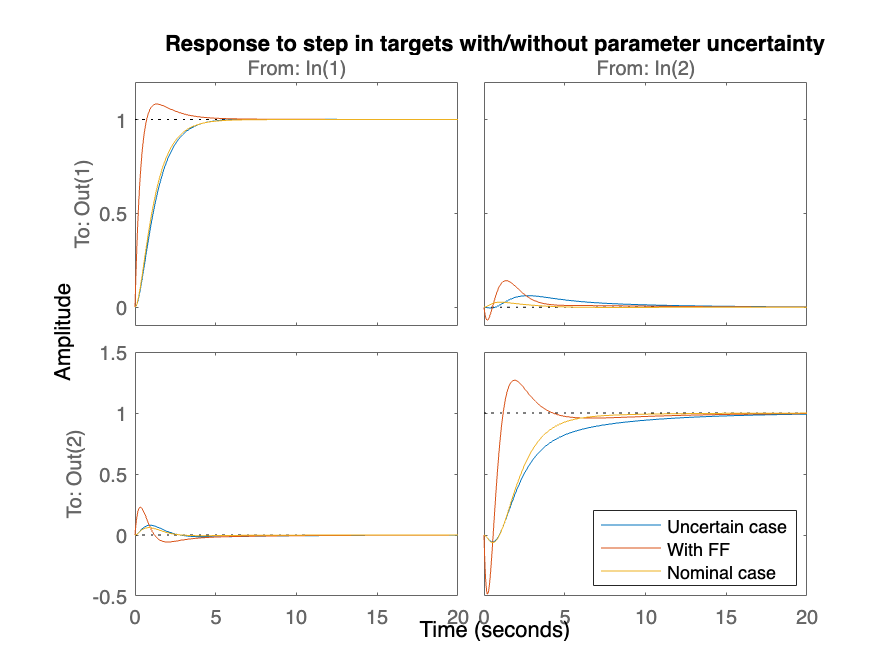

% system parameters
A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
C=[3 2 1 0;0 0 0 1];
D = zeros(2,2);
%    Model parameters differ from true system
Am=[-0. -0.4 -0.65 0.2;0.4 1 .72 .5;-0.3 1 1 0;0.8 1.1 -0.4 0]; 
Bm=[1.2 0;-1 1;0 0.35;-1.1 2];
Cm=[3.2 2 1 0;0 0 0 1];

% Augmented model and  augmented process
Aaugm = [Am,zeros(4,2);-Cm,zeros(2,2)];
Baugm = [Bm;zeros(2,2)];
Caugm = [Cm,zeros(2,2)];
Aaugp = [A,zeros(4,2);-C,zeros(2,2)];
Baugp = [B;zeros(2,2)];
Caugp = [C,zeros(2,2)];

Qaug = [Cm'*Cm,zeros(4,2);zeros(2,4),eye(2)]; 
Raug=eye(2);
Km=lqr(Aaugm,Baugm,Qaug,Raug);
% Feedforward design
P = -inv(Cm*inv(Am-Bm*Km(:,1:4))*Bm);  % use the part of K not depending on the error state
Br = [zeros(4,2);eye(2)];
BrP = [B*P;eye(2)];
Gclosed = ss(Aaugp-Baugp*Km,Br,Caugp,D);
GclosedP = ss(Aaugp-Baugp*Km,BrP,Caugp,D);
Gclosed0 = ss(Aaugm-Baugm*Km,Br,Caugm,D);  

step(Gclosed,GclosedP,Gclosed0,20);
title('Response to step in targets with/without parameter uncertainty')
legend('Uncertain case','With FF','Nominal case','Location','southeast')

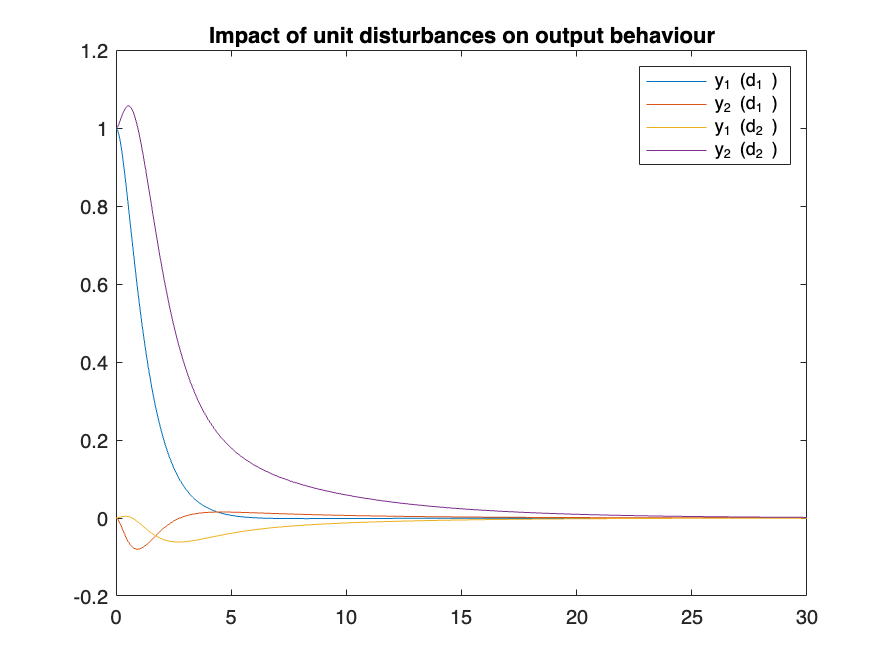


% Augmentation for disturbance case
Bd = [Br,[zeros(4,2);-eye(2)]];   % output disturbance so add a column of zeros to B
Cd = Caugp; 
Dd = [D, eye(2)];     % add  extra column for disturbance impact 
Gclosed_d = ss(Aaugp-Baugp*Km,Bd,Cd,Dd);  % with no FF


[y,t] = step(Gclosed_d,30);
plot(t,y(:,:,3),t,y(:,:,4))
title('Impact of unit disturbances on output behaviour')
legend('y_1 (d_1 )','y_2 (d_1 )','y_1 (d_2 )','y_2 (d_2 )')

### Remark: Including integral action and deviation variables

The problem with the optimisation of:


$$J=\int W^{T\;} Q\;W+U^T R\;U\ldotp \textrm{dt};\;\;W=\left\lbrack \begin{array}{c}
\dot{X} \\
\dot{Z} 
\end{array}\right\rbrack ;\;\frac{d\;Z}{\textrm{dt}}=r-C\;X\;\;$$


Is that the steady-state values of *W,U* are not zero and thus the cost function is unbounded. An easy way to make this bounded is to use linearity/superposition and postulate a more sensible and equivalent performance index of the form here, that is, using deviations relative to steady-state:


$$J=\int {\tilde{W} }^{T\;} Q\;\tilde{W} +{\tilde{U} }^T R\;\tilde{U} \ldotp \textrm{dt};\;\tilde{W} =\left\lbrack \begin{array}{c}
X-X_{\textrm{ss}} \\
Z-Z_{\textrm{ss}} 
\end{array}\right\rbrack ;\;\;\;\tilde{U} =U-U_{\textrm{ss}} ;\;\;\;\;\;\frac{d\;\tilde{Z} }{\textrm{dt}}=-C\;\tilde{X} \;\;$$


The optimal control law for this problem will take the form:  $\tilde{U} =-K\;\tilde{W}$. This implies that:

$U-U_{\textrm{ss}} =-K\left(W-W_{\textrm{ss}} \right)$  or $U=-K\;W+KW_{\textrm{ss}} +U_{\textrm{ss}}$

However, it is easy to show that:   $KW_{\textrm{ss}} +U_{\textrm{ss}} =-\;{\left(C{\left\lbrack A-B\;\hat{K} \right\rbrack }^{-1} B\right)}^{-1} r=P\;r$ where $\hat{K}$ extracts only the parts multiplying on *X*.  Hence there is an argument that the feedforward term should logically be included.